%% -------- PARAMETERS --------
signal_length = 20;        % number of bits
M  = 1000;                   % samples (chips) per bit
Pn = 1;                   % uniform-noise power, Pn = a^2/3
A  = 10;          % sinusoid amplitude (interferer)
w0 = 0.17*pi;             % sinusoid rad/sample, 0 < w0 < pi (avoid harmonics)

% PN (LFSR)
init = [1 1 1 1 1 0 1];   % 7-stage seed (non-zero)
taps = [1 4 7];           % feedback taps (indices, 1 = leftmost/MSB)

rng(1);                   % reproducibility

%% -------- TX --------
bits      = binary_data_gen(signal_length);     % 0/1
s_nrz     = modulator(M, bits);                 % ±1, length = signal_length*M
pn        = pn_sequence_lfsr(signal_length, M, init, taps);  % ±1, same length
tx_dsss   = s_nrz .* pn;                        % DSSS signal

%% -------- CHANNEL: uniform noise + sinusoid --------
a  = sqrt(3*Pn);                                 % so that Pn = a^2/3
w  = (2*rand(size(tx_dsss)) - 1) * a;            % uniform in [-a, a]
n  = 0:numel(tx_dsss)-1;
tone = A * sin(w0 * n);                          % narrowband interferer
rx  = tx_dsss + w + tone;                        % received

%% -------- RX: despread, integrate-and-dump, decide --------
despread = rx .* pn;                              % multiply by SAME PN

% integrate-and-dump (sum each block of M samples)
demod_dsss = sum( reshape( pad_to_multM(despread, M), M, [] ).', 2 ).'; % 1×Nbits
bits_hat_dsss = demod_dsss >= 0;                  % threshold at 0

% BER with DSSS
err_dsss = sum(bits_hat_dsss ~= bits);
BER_dsss = err_dsss/numel(bits);

%% -------- Baseline (no PN) for comparison --------
rx_noPN = s_nrz + w + tone;
demod_noPN = sum( reshape( pad_to_multM(rx_noPN, M), M, [] ).', 2 ).';
bits_hat_noPN = demod_noPN >= 0;
err_noPN = sum(bits_hat_noPN ~= bits);
BER_noPN = err_noPN/numel(bits);

fprintf('DSSS:  errors=%d  BER=%.3g   |   No PN: errors=%d  BER=%.3g\n', ...
        err_dsss, BER_dsss, err_noPN, BER_noPN);

DSSS:  errors=0  BER=0   |   No PN: errors=0  BER=0


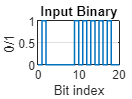


%% -------- Plots (optional, compact) --------
% bit-domain edges so the last step reaches the end
xBits  = 0:signal_length; 
yBits  = [bits, bits(end)];
figure; stairs(xBits, yBits, 'LineWidth',1); grid on;
title('Input Binary'); xlabel('Bit index'); ylabel('0/1');

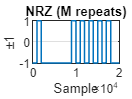


xSamp  = 0:numel(s_nrz);
figure; stairs(xSamp, [s_nrz s_nrz(end)], 'LineWidth',1); grid on;
title('NRZ (M repeats)'); xlabel('Sample'); ylabel('±1');

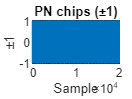


figure; stairs(xSamp, [pn pn(end)], 'LineWidth',1); grid on;
title('PN chips (±1)'); xlabel('Sample'); ylabel('±1');

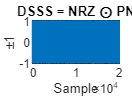


figure; stairs(xSamp, [tx_dsss tx_dsss(end)], 'LineWidth',1); grid on;
title('DSSS = NRZ ⊙ PN'); xlabel('Sample'); ylabel('±1');

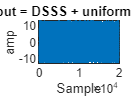


figure; plot(0:numel(rx)-1, rx, 'LineWidth',1); grid on;
title('Channel output = DSSS + uniform noise + sinusoid'); xlabel('Sample'); ylabel('amp');

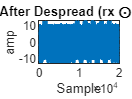


% show despread (still noisy per-sample) and per-bit sums
figure; plot(0:numel(despread)-1, despread, 'LineWidth',1); grid on;
title('After Despread (rx ⊙ PN)'); xlabel('Sample'); ylabel('amp');

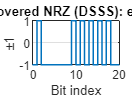


figure; stairs(xBits, [bits_hat_dsss, bits_hat_dsss(end)]*2-1, 'LineWidth',1); grid on;
title(sprintf('Recovered NRZ (DSSS): errors=%d', err_dsss));
xlabel('Bit index'); ylabel('±1');





%% ---------- SWEEPS (runs after the single-run above) ----------
Ms        = [50 100 500 1000];
max_chips = 2e6;
Pn        = 1;
init_sw   = init;
taps_sw   = taps;

Nfreq = 10;   % <-- average over 10 random tone frequencies per M

% === Sweep 1: A = M ===
BER_dsss_Am = zeros(size(Ms));
BER_noPN_Am = zeros(size(Ms));

for k = 1:numel(Ms)
    Mk    = Ms(k);
    Ak    = 1.0 * Mk;
    Nbits = floor(max_chips / Mk);

    [BER_dsss_Am(k), BER_noPN_Am(k)] = run_one_avg(Nbits, Mk, Pn, Ak, init_sw, taps_sw, Nfreq);
    fprintf('[A=M]  M=%4d  A=%6.1f  Nbits=%7d  ->  BER_DSSS=%.4f  BER_noPN=%.4f\n', ...
            Mk, Ak, Nbits, BER_dsss_Am(k), BER_noPN_Am(k));
end

[A=M]  M=  50  A=  50.0  Nbits=  40000  ->  BER_DSSS=0.4612  BER_noPN=0.4636
[A=M]  M= 100  A= 100.0  Nbits=  20000  ->  BER_DSSS=0.3551  BER_noPN=0.4900
[A=M]  M= 500  A= 500.0  Nbits=   4000  ->  BER_DSSS=0.3902  BER_noPN=0.4995
[A=M]  M=1000  A=1000.0  Nbits=   2000  ->  BER_DSSS=0.3681  BER_noPN=0.4991


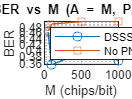


figure; semilogy(Ms, BER_dsss_Am, '-o', Ms, BER_noPN_Am, '-s'); grid on;
xlabel('M (chips/bit)'); ylabel('BER'); title('BER vs M (A = M, P_n = 1)');
legend('DSSS (with PN)','No PN','Location','southwest');


% === Sweep 2: fixed A = 50 ===
A_fixed     = 50;
BER_dsss_Af = zeros(size(Ms));
BER_noPN_Af = zeros(size(Ms));

for k = 1:numel(Ms)
    Mk    = Ms(k);
    Nbits = floor(max_chips / Mk);

    [BER_dsss_Af(k), BER_noPN_Af(k)] = run_one_avg(Nbits, Mk, Pn, A_fixed, init_sw, taps_sw, Nfreq);
    fprintf('[A=50] M=%4d  A=%6.1f  Nbits=%7d  ->  BER_DSSS=%.4f  BER_noPN=%.4f\n', ...
            Mk, A_fixed, Nbits, BER_dsss_Af(k), BER_noPN_Af(k));
end

[A=50] M=  50  A=  50.0  Nbits=  40000  ->  BER_DSSS=0.4622  BER_noPN=0.4682
[A=50] M= 100  A=  50.0  Nbits=  20000  ->  BER_DSSS=0.2523  BER_noPN=0.4695
[A=50] M= 500  A=  50.0  Nbits=   4000  ->  BER_DSSS=0.0000  BER_noPN=0.4555
[A=50] M=1000  A=  50.0  Nbits=   2000  ->  BER_DSSS=0.0000  BER_noPN=0.4498


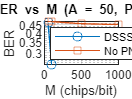


figure; semilogy(Ms, BER_dsss_Af, '-o', Ms, BER_noPN_Af, '-s'); grid on;
xlabel('M (chips/bit)'); ylabel('BER'); title('BER vs M (A = 50, P_n = 1)');
legend('DSSS (with PN)','No PN','Location','southwest');





%% ====== FUNCTIONS ======

function binary_signal = binary_data_gen(signal_length)
    binary_signal = randi([0, 1],1, signal_length);
end

function mod_signal = modulator(M, binary_signal)
    mod_signal = repelem(2*binary_signal - 1, M);
end

% Pad a row vector with zeros to make its length a multiple of M.
function y = pad_to_multM(x, M)
    L = numel(x); remL = mod(L, M);
    if remL == 0, y = x; else, y = [x, zeros(1, M - remL)]; end
end

function pn = pn_sequence_lfsr(num_bits, chips_per_bit, init, taps)
    if all(init == 0), error('init state must be nonzero.'); end
    N = num_bits * chips_per_bit;
    reg = logical(init(:).'); chips01 = false(1, N);
    for k = 1:N
        chips01(k) = reg(end);                 % output = rightmost stage
        fb = mod(sum(reg(taps)), 2);           % XOR of taps
        reg = [logical(fb) reg(1:end-1)];      % shift in feedback on left
    end
    pn = 2*double(chips01) - 1;                % map {0,1} -> {-1,+1}
end



function [BER_dsss, BER_noPN] = run_one(Nbits, M, Pn, A, w0, init, taps)
    % bits & NRZ
    bits  = randi([0 1], 1, Nbits);
    s_nrz = repelem(2*bits-1, M);

    % PN & spreading
    pn  = pn_sequence_lfsr(Nbits, M, init, taps);
    tx  = s_nrz .* pn;

    % channel: uniform noise + sinusoid with random phase
    a    = sqrt(3*Pn);
    w    = (2*rand(size(tx)) - 1) * a;
    n    = 0:numel(tx)-1;
    phi  = 2*pi*rand;                 % randomize jammer phase per run
    tone = A * sin(w0*n + phi);
    rx   = tx + w + tone;

    % despread + integrate & dump
    despread  = rx .* pn;
    y_dsss    = sum(reshape(pad_to_multM(despread, M), M, []).', 2).';
    bhat_dsss = (y_dsss >= 0);
    BER_dsss  = mean(bhat_dsss ~= bits);

    % baseline: no PN
    rx0   = s_nrz + w + tone;
    y0    = sum(reshape(pad_to_multM(rx0, M), M, []).', 2).';
    bhat0 = (y0 >= 0);
    BER_noPN = mean(bhat0 ~= bits);
end


function [BERd_avg, BER0_avg] = run_one_avg(Nbits, M, Pn, A, init, taps, Nfreq)
    BERd = 0; BER0 = 0;
    for r = 1:Nfreq
        % draw tone uniformly in [0, ω_max] with ω_max proportional to 1/M
        % so many draws are "low" and stressful for the no-PN integrator
        w0 = (2*pi/M) * (0.5 + 0.5*rand);   % ~[π/M, 2π/M]
        [bd, b0] = run_one(Nbits, M, Pn, A, w0, init, taps);
        BERd = BERd + bd;  BER0 = BER0 + b0;
    end
    BERd_avg = BERd / Nfreq;  BER0_avg = BER0 / Nfreq;
end

